# Hybrid powertrain - control

*Ing. David Vošahlík*

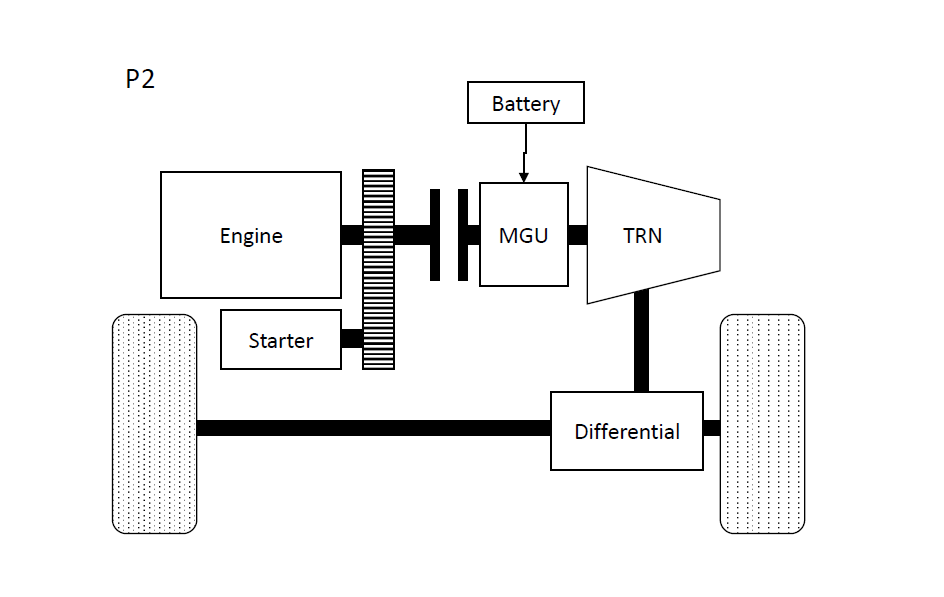

## Introduction

The modeling activity was covered already in past two seminars. Today a Power Split control will be covered. The Power split ultimate task is to split the power demand from driver onto the individual powertrain power sources - ICE and MGU. The control strategy should split the driver torque request to ICE torque and MGU torque. It can be done in many ways. Often some optimality is chased so that the control strategy minimizes fuel consumption, battery wear, etc. Today we will introduce state-of-the-art approach called ECMS (Equivalent Consumption Minimization Strategy) control. 

### ECMS

The ECMS strategy main idea is to minimize the consumption, where the Battery power is transformed to the so called equivalent consumption. The ECMS then tries to minimize the fuel consumption, where it relys on approximation that minimum consumed energy for the trip is approximately equal to minimization of power at individual trip instants.

where $\dot{m_f }$is a sum of the ICE fuel consumption and the battery equivalent fuel consumption

The battery equivalent fuel consumption is computed as:


$${\dot{m} }_{f\;\mathrm{bat}} =\frac{\eta {\;}_{\mathrm{MGU}} \cdot P_{\mathrm{Batt}} }{\eta {\;}_{\mathrm{el}} }$$


where $\eta {\;}_{\textrm{MGU}}$is MGU efficiency, $\eta {\;}_{\textrm{el}}$ is electric system (wiring to the battery and MGU) efficiency, and $P_{\textrm{Batt}}$ is battery power. Often the efficiencies are merged to a single parameter called equivalence factor $\lambda \;\ldotp$ Finally, the function that has to be minimized is 


$$\min_{{\mathrm{ICE}}_{\mathrm{tq}} ,{\mathrm{MGU}}_{\mathrm{tq}} } J\left({\mathrm{ICE}}_{\mathrm{tq}} ,{\mathrm{MGU}}_{\mathrm{tq}} \right)=\dot{m_f } \left({\mathrm{ICE}}_{\mathrm{tq}} \right)+\lambda \;P_{\mathrm{Batt}} \left({\mathrm{MGU}}_{\mathrm{tq}} \right)=\dot{m_f } \left({\mathrm{ICE}}_{\mathrm{tq}} \right)+\lambda \;V_{\mathrm{Batt}} I\left({\mathrm{MGU}}_{\mathrm{tq}} \right)\;$$


Your task will be to implement ECMS strategy, that will control the high fidelity P2 powertrain model you modeled in the previous seminars. The only thing you have to implement is the ECMS in the for loop in the prepared script. A simple test scenario is here prepared for you.

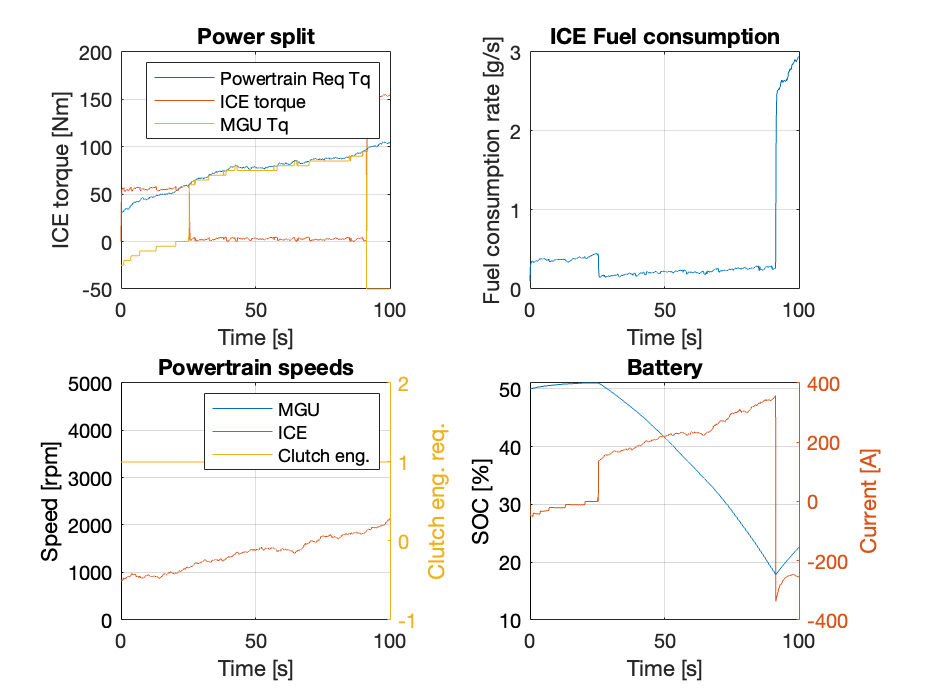

% Setup the constants
car = InitializeCar();
% Time vector [s]
Ts = 0.1;
time = 0:Ts:100;
% create a vehicle velocity vector and other derived test signals
Veh_Spd = max(8, cumsum([10, 0.02*ones(1, numel(time) - 1)])) + 2 + movmean(10*randn(1, numel(time)), 100);
% Driver torque request [Nm] at wheels. Usually this is the signal you get from mapping of acceleration pedal
Drvr_TqReq = 40*ones(1, numel(time)) + movmean(100*randn(1, numel(time)), 400) + cumsum([1, 0.06*ones(1, numel(time) - 1)]);
% Compute the APS (Accelerator pedal position) [%] -> normalized driver torque demand
APS = Drvr_TqReq/130;
Cltch_engReq = 1;
 % states [ICE_Tq, Bat_current, Bat_U1, Bat_U2, Bat_SOC, trsm_gear, trsm_counter, cltch_eng]
x0_P2 = [0; 0; 0; 0; 50; 1; 0; 1];

x = zeros(numel(x0_P2), numel(time));
x(:,1) = x0_P2;
y = zeros(4, numel(time));
u = zeros(5, numel(time));
for k = 1:numel(time)

    % IMPLEMENT an ECMS control strategy following the Driver wheel torque request Drvr_TqReq.
    Cltch_engReq = 1;
    [ICE_TqReq, MGU_TqReq] = ECMS(Drvr_TqReq(k), Veh_Spd(k)/car.Whl_r/(2*pi)*60, x(3:5,k), x(1,k), car);
    u(:,k) = [ICE_TqReq; MGU_TqReq; Veh_Spd(k); APS(k); Cltch_engReq];
    if k < numel(time)
        [x(:,k + 1), y(:,k)] = P2Powertrain(x(:,k),u(:,k),car, Ts);
    else
        [~, y(:,k)] = P2Powertrain(x(:,k),u(:,k),car, Ts);
    end
end

% Plot the important signals
figure();
clf;
subplot(221);
plot(time, Drvr_TqReq')
hold on;
plot(time, x(1,:));
plot(time, u(2,:));
grid on;
xlabel('Time [s]');
ylabel('ICE torque [Nm]');
legend('Powertrain Req Tq', 'ICE torque', 'MGU Tq');
title('Power split');

subplot(222);
plot(time, y(1,:));
grid on;
xlabel('Time [s]');
ylabel('Fuel consumption rate [g/s]');
title('ICE Fuel consumption');

subplot(223);
plot(time, y(3,:)); % Pwr_Spd
hold on;
plot(time, y(4,:)); % ICE_Spd
grid on;
xlabel('Time [s]');
ylabel('Speed [rpm]');
ylim([-10 5000]);
yyaxis right;
plot(time, u(5,:)); % Cltch_engReq
grid on;
xlabel('Time [s]');
ylabel('Clutch eng. req.');
ylim([-1 2]);
legend('MGU', 'ICE', 'Clutch eng.');
title('Powertrain speeds');


subplot(224);
plot(time, x(5,:));
grid on;
xlabel('Time [s]');
ylabel('SOC [%]');
title('Battery');
yyaxis right;
plot(time, x(2,:)); % Cltch_engReq
grid on;
xlabel('Time [s]');
ylabel('Current [A]');

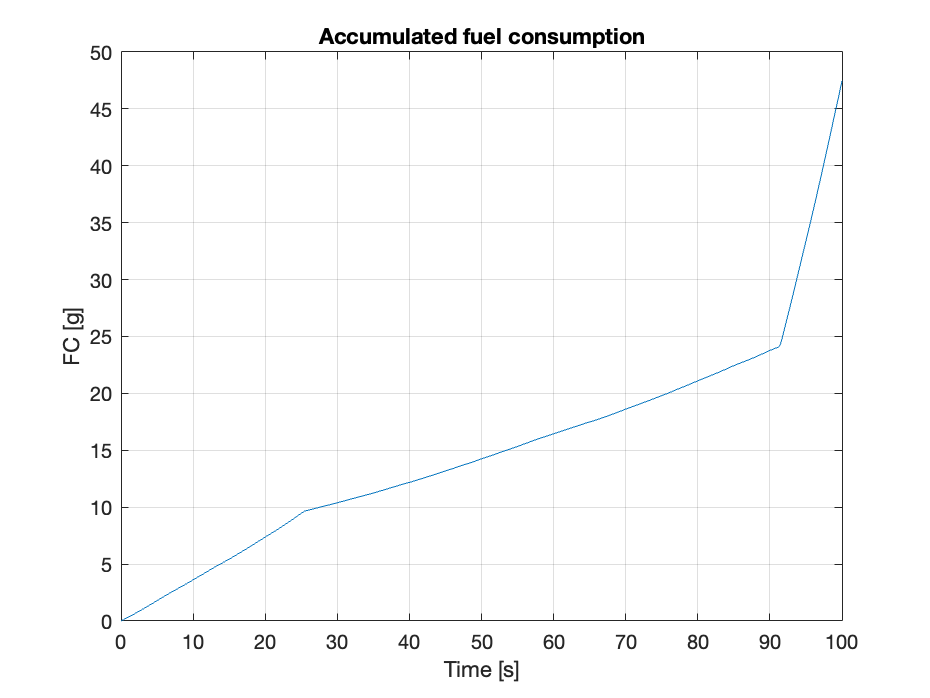


figure();
clf;
plot(time, cumsum(y(1,:)*Ts))
grid on;
xlabel('Time [s]');
ylabel('FC [g]');
title('Accumulated fuel consumption');

### Further ECMS improvement

If you take a closer look on the ECMS you implemented you can see it is rather very simple version not usable for real deployment. There are couple of problems that still need to be handled. E.g., the SOC value is not in any way influencing the torque split. Therefore, the SOC may be unstable. This is often solved as stating the equivalence factor $\lambda \;$as a function of SOC $\lambda \left(\textrm{SOC}\right)$ to respect the SOC limits. Try to come up with your solution.

Next thing that often differentiate the hybrid control strategies is the ICE on/off handling. Try to come up with your own on/off strategy.


$$\min_{{\mathrm{ICE}}_{\mathrm{tq}} ,{\mathrm{MGU}}_{\mathrm{tq}} } J\left({\mathrm{ICE}}_{\mathrm{tq}} ,{\mathrm{MGU}}_{\mathrm{tq}} \right)=\dot{m_f } \left({\mathrm{ICE}}_{\mathrm{tq}} \right)+\lambda \;P_{\mathrm{Batt}} \left({\mathrm{MGU}}_{\mathrm{tq}} \right)=\dot{m_f } \left({\mathrm{ICE}}_{\mathrm{tq}} \right)+\lambda \;V_{\mathrm{Batt}} I\left({\mathrm{MGU}}_{\mathrm{tq}} \right)\;$$



$$\dot{m_f } \left({\mathrm{ICE}}_{\mathrm{tq}} \right)+\lambda \;V_{\mathrm{Batt}} I\left({\mathrm{MGU}}_{\mathrm{tq}} \right)$$


function [ICE_Tq, MGU_Tq] = ECMS(Drvr_TqReq, MGU_Spd, x_bat, x_ice, car) % Function for ECMS computation
MGU_min = interp1(car.MGU.MinTq.Spd, car.MGU.MinTq.Tq, MGU_Spd, 'linear', 'extrap');
MGU_max = interp1(car.MGU.MaxTq.Spd, car.MGU.MaxTq.Tq, MGU_Spd, 'linear', 'extrap');

ICE_max = interp1(car.ICE.MaxTq.Spd, car.ICE.MaxTq.Tq, MGU_Spd, 'linear', 'extrap');
ICE_min = interp1(car.ICE.MinTq.Spd, car.ICE.MinTq.Tq, MGU_Spd, 'linear', 'extrap');

% lambda = .000035;
lambda = 0.00005;

Dr = Drvr_TqReq;
i = MGU_min;
array_mgu = [];
array_ice = [];
k = 0;
while(i<=Dr)
    array_mgu(end+1) = i;
    array_ice(end+1) = Dr-i;
    i = i+5;
    k = k+1;
end
costs = [];

for i=1:k
    Vbat  = BatOutput(x_bat,0,car);
    I     = MGUOutput([array_mgu(i),MGU_Spd,Vbat],car);
    FC    = interp2(car.ICE.FC.Spd, car.ICE.FC.Tq, car.ICE.FC.FC, MGU_Spd, array_ice(i), 'spline'); 
    costs(end+1)= FC +lambda*Vbat*I;
end
[J,I] = min(costs);
ICE_Tq = array_ice(I); % Please IMPLEMENT the ICE Tq request
MGU_Tq = array_mgu(I); % Please IMPLEMENT the MGU Tq request
end

function [y_MGU] = MGUOutput(u_MGU, car) % output function for MGU - no dynamics
% u_MGU - is the input [Torque MGU [Nm], Speed MGU [rpm], Battery Voltage [V]]
% y_MGU - is the output [Current MGU [A]]
% car - structure with the parameters. Check InitializeCar.m function

% IMPLEMENT output function for MGU model. Use the constants defined in the car.MGU

u_MGU(1) = max(min(u_MGU(1), interp1(car.MGU.MaxTq.Spd, car.MGU.MaxTq.Tq, u_MGU(2), 'spline')), interp1(car.MGU.MinTq.Spd, car.MGU.MinTq.Tq, u_MGU(2), 'spline'));

pwrMGU = u_MGU(1)*u_MGU(2)/60*2*pi;
eta = interp2(car.MGU.eta.Spd, car.MGU.eta.Tq, car.MGU.eta.eta, u_MGU(2), u_MGU(1), 'spline');
y_MGU = eta^(sign(-1*pwrMGU))*pwrMGU/u_MGU(3);
end

function [xDot_bat] = BatStateDerivative(x_bat, u_bat, car)
% State derivative function for battery - continuous time dynamics
% x_bat - is the state [U1 [V], U2 [V], SOC [%]]
% u_bat - is the input [Current [A]]
% car - structure with the parameters. Check InitializeCar.m function

% Implement the continuous time dynamic equations
U1_dot = -1/(car.Bat.R1*car.Bat.C1)*x_bat(1) + 1/car.Bat.C1*u_bat(1);
U2_dot = -1/(car.Bat.R2*car.Bat.C2)*x_bat(2) + 1/car.Bat.C2*u_bat(1);
SOC_dot = -car.Bat.eta/(car.Bat.C)*u_bat(1);

% Sort the derivative values to the vector
xDot_bat = [U1_dot;U2_dot;SOC_dot];
end

function [y_bat] = BatOutput(x_bat, u_bat, car)
% output function for battery - continuous time dynamics
% x_bat - is the battery state [U1 [V], U2 [V], SOC [%]]
% u_bat - is the battery input [Current [A]]
% y_bat - is the battery output [Terminal voltage [V]]
% car - structure with the parameters. Check InitializeCar.m function

% Compute the terminal voltage output
y_bat = ocv(x_bat(3)) - x_bat(1) - x_bat(2) - u_bat*car.Bat.R0;
end


function voltage = ocv(SOC)
% Copmute the open circuit voltage [V] for the provided SOC [%]
voltage = 38 + 0.295*SOC - 0.01*SOC^2 + 1.9694e-04*SOC^3 - 1.652e-06*SOC^4 + 5.234e-09*SOC^5;
end


function [xDot_ice] = ICEStateDerivative(x_ice, u_ice, car) % State derivative function for ICE - continuous time dynamics
% x_ice - is the state [brake torque [Nm]]
% u_ice - is the input [brake torque req [Nm], speed [rpm]]
% car - structure with the parameters. Check InitializeCar.m function


% IMPLEMENT a state derivative function for ICE model. Use the constants defined in the car.ICE
tau = car.ICE.tau;
u_ice(1) = max(min(u_ice(1), interp1(car.ICE.MaxTq.Spd, car.ICE.MaxTq.Tq, u_ice(2), 'spline')), interp1(car.ICE.MinTq.Spd, car.ICE.MinTq.Tq, u_ice(2), 'spline'));
xDot_ice = 1/tau*(u_ice(1) - x_ice(1));
end

function [y_ice] = ICEOutput(x_ice, u_ice, car) % output function for ICE - continuous time dynamics
% x_ice - is the state [brake torque [Nm]]
% u_ice - is the input [brake torque req [Nm], speed [rpm]]
% y_ice - is the output [actual brake torque [Nm], ICE FC [g/s]]
% car - structure with the parameters. Check InitializeCar.m function


% IMPLEMENT an output function for ICE model. Use the constants defined in the car.ICE
fc = interp2(car.ICE.FC.Spd, car.ICE.FC.Tq, car.ICE.FC.FC, u_ice(2), x_ice, 'spline');
y_ice = [x_ice; fc];
end


function [Trsm_GrNxt] = GSS(APS, Veh_V, Trsm_GrAct, car) % Gear shifting strategy
% APS - Accelerator pedal position [%]
% Veh_V - Vehicle velocity [km/h]
% Trsm_GrAct - Actual gear [-]
% car - structure with the parameters. Check InitializeCar.m function

% IMPLEMENT a gear shifting strategy. Use the constants defined in the car.GSS
speed_ThrUp = car.GSS.speed_ThrUp + 3 - 6*APS;
speed_ThrDwn = car.GSS.speed_ThrDwn + 3 - 6*APS;

grPl1 = min(5, Trsm_GrAct);
grM1 = max(1, Trsm_GrAct - 1);
if speed_ThrUp(grPl1) < Veh_V
    Trsm_GrNxt = grPl1 + 1;
elseif speed_ThrDwn(grM1) > Veh_V
    Trsm_GrNxt = grM1;
else
    Trsm_GrNxt = Trsm_GrAct;
end
end

function [xk1_trsm] = TrsmStateTransition(xk_trsm, u_trsm, Ts, car) % State transition function for transmission - discrete time dynamics
% xk1_trsm - is the next time step Ts + 1 value of the transmission state [transmission gear number [-], counter [-]]
% u_trsm - is the transmission input [Torque pwr [Nm], Speed whl [rpm], Gear req[-]]
% Ts - The sampling time for the transmission.
% car - structure with the parameters. Check InitializeCar.m function


% IMPLEMENT a state transition function for transmission. Use the constants defined in the car.Trsm
delay = car.Trsm.delay;

% Start counting if the gear change comes. Reset the counter otherwise 
if u_trsm(3) ~= xk_trsm(1)
    xk_trsm(2) = xk_trsm(2) + Ts;
else
    xk_trsm(2) = 0;
end

% Shift if the counter reached the delay value
if xk_trsm(2) >= delay
    xk_trsm(1) = min(6, max(1, max(xk_trsm(1) - 1, min(xk_trsm(1) + 1, u_trsm(3)))));
    xk_trsm(2) = 0;
end


xk1_trsm = xk_trsm;
end

function [y_trsm] = TrsmOutput(xk_Trsm, u_trsm, car) % output function for transmission
% xk_trsm - is the next time step Ts + 1 value of the transmission state [transmission gear number [-], counter [-]]
% u_trsm - is the transmission input [Torque pwr [Nm], Speed whl [rpm], Gear req[-]]
% y_trsm - is the transmission output [Torque whl [Nm]; Speed pwr [rpm]]
% car - structure with the parameters. Check InitializeCar.m function

% IMPLEMENT an output function for transmission. Use the constants defined in the car.Trsm

y_trsm = zeros(2,1);
% Wheel torque 
y_trsm(1) = u_trsm(1)*car.Trsm.GearRatios(xk_Trsm(1));
% Powertrain speed
y_trsm(2) = u_trsm(2)*car.Trsm.GearRatios(xk_Trsm(1));
end

function [xDot_cltch] = CltchStateDerivative(x_cltch, u_cltch, car) % State derivative function for clutch - continuous time dynamics
% x_cltch - is the clutch state [Engagement [-]]
% u_cltch - is the clutch input [Torque_eng [Nm], Speed_mgu [rpm], Engagement_req [-]]
% car - structure with the parameters. Check InitializeCar.m function


% IMPLEMENT a state derivative function for clutch model. Use the constants defined in the car.Cltch
tau = car.Cltch.tau;
xDot_cltch = 1/tau*(min(1,max(0,u_cltch(3))) - x_cltch);
end

function [y_cltch] = CltchOutput(x_cltch, u_cltch) % output function for clutch
% x_cltch - is the clutch state [Engagement [-]]
% u_cltch - is the clutch input [Torque_eng [Nm], Speed_mgu [rpm], Engagement_req [-]]
% y_cltch - is the clutch output [Torque mgu [Nm], Speed eng [rpm]]

% IMPLEMENT output function for clutch model. Use the constants defined in the car.Cltch

y_cltch = zeros(2,1);
y_cltch(1) = u_cltch(1)*x_cltch(1);
y_cltch(2) = u_cltch(2)*x_cltch(1);
end





function dxdt = myode(t,x,ut,u, fun) % helper function to use within ode45 solver function
uInterp = zeros(size(u, 1), 1);
for i = 1:size(u, 1)
    uInterp(i) = interp1(ut,u(i,:),t); % Interpolate the data set (ut,u) at time t
end
dxdt = fun(x, uInterp); % Evaluate ODE at time t
end

function [x_k1, y] = P2Powertrain(x,u,car, Ts)
 % states [ICE_Tq, Bat_current, Bat_U1, Bat_U2, Bat_SOC, trsm_gear, trsm_counter, cltch_eng]
 % inputs [ICE tqReq, MGU tqReq, Veh_Spd, APS, cltch_engReq]
 % outputs [ICE_FC, Whl_Tq, Pwr_Spd, ICE_Spd]

 x_bat = x(3:5);
 u_bat = x(2);
 [~,x_k1Bat] =  ode45(@(t,x) BatStateDerivative(x, u_bat, car), [0 Ts], x_bat);
 Bat_VTrm = BatOutput(x_bat, u_bat, car);

 Veh_Spd = u(3)/3.6;
 Whl_Spd = Veh_Spd/car.Whl_r/(2*pi)*60;
 ActGear = x(6);
 Pwr_Spd = TrsmOutput(ActGear, [0; Whl_Spd], car);
 Pwr_Spd = Pwr_Spd(2);

 MGU_Tq = u(2);
 u_MGU = [MGU_Tq; Pwr_Spd; Bat_VTrm];
 Bat_A = MGUOutput(u_MGU, car);

 ICE_Tq = x(1);
 % [Engagement [-]]
 x_cltch = x(8);
 % [Torque_eng [Nm], Speed_mgu [rpm], Engagement_req [-]]
 u_cltch = [ICE_Tq; Pwr_Spd; u(5)];
 % [Engagement [-]]
 [~,x_k1Cltch] =  ode45(@(t,x) CltchStateDerivative(x, u_cltch, car), [0 Ts], x_cltch);


 % [Torque mgu [Nm], Speed eng [rpm]]
 [y_cltch] = CltchOutput(x_cltch, u_cltch);
 Cltch_Tq = y_cltch(1);
 ICE_Spd = y_cltch(2);


 ICE_TqReq = u(1);
 % [brake torque [Nm]]
 x_ice = [ICE_Tq];
 u_ice = [ICE_TqReq; ICE_Spd];
 % [brake torque [Nm]]
 [~,x_k1Ice] =  ode45(@(t,x) ICEStateDerivative(x, u_ice, car), [0 Ts], x_ice);
 [y_ice] = ICEOutput(x_ice, u_ice, car);
 ICE_FC = y_ice(2);



 APS = u(4);
 Trsm_GrNxt = GSS(APS, Veh_Spd, ActGear, car);

 Pwr_Tq = Cltch_Tq + MGU_Tq;
 xk_trsm = [ActGear; x(7)];  % [transmission gear number [-], counter [-]]
 u_trsm = [Pwr_Tq; Whl_Spd; Trsm_GrNxt]; %  [Torque pwr [Nm], Speed whl [rpm], Gear req[-]]
 [y_trsm] = TrsmOutput(xk_trsm, u_trsm, car); % [Torque whl [Nm]; Speed pwr [rpm]]
 xk1_trsm = TrsmStateTransition(xk_trsm, u_trsm, Ts, car);

 Pwr_Spd = y_trsm(2);
 Whl_Tq = y_trsm(1);

 % states [ICE_Tq, Bat_current, Bat_U1, Bat_U2, Bat_SOC, trsm_counter, trsm_gear, cltch_eng]
 x_k1 = [x_k1Ice(end,:)'; Bat_A; x_k1Bat(end,:)'; xk1_trsm; x_k1Cltch(end,:)'];
 % outputs [ICE_FC, Whl_Tq, Pwr_Spd, ICE_Spd]
 y = [ICE_FC, Whl_Tq, Pwr_Spd, ICE_Spd];
 end